% independent variable
x = linspace(0, 10, 100);

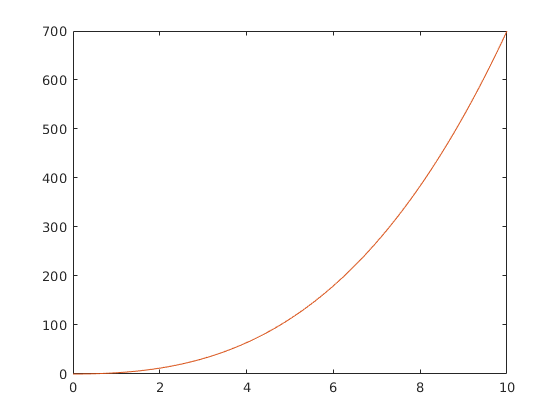

% basic case
y = 0 + 2.*x.^2 + .5 .* x.^3;
m = 2;
p = [2,3];
b = [0,2,.5];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

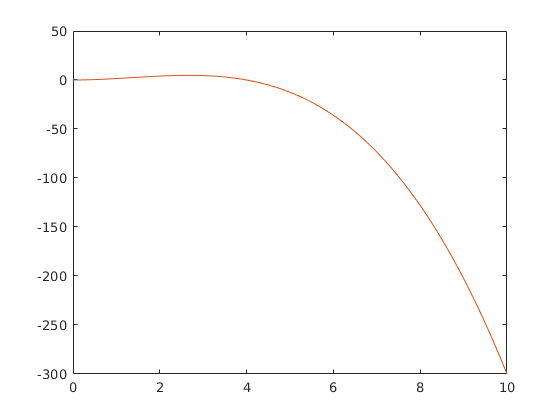

% flip sign on cubic
y = 0 + 2.*x.^2 - .5 .* x.^3;
m = 2;
p = [2,3];
b = [0,2,-.5];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

In this next section, I try to reproduce shapes from  Fig. 1a in Royston and Altman 1994.

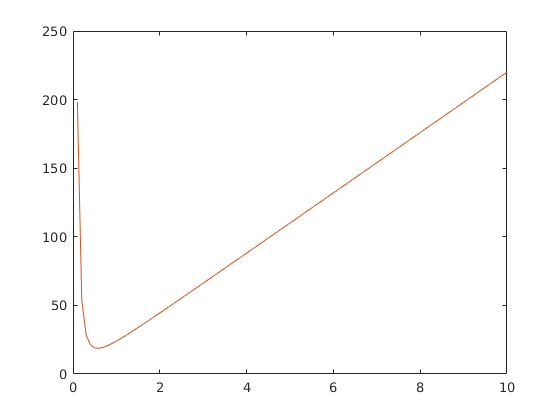

% -2, 1
y = 0 + 2.*x.^-2 + 22 .* x.^1;
m = 2;
p = [-2,1];
b = [0,2,22];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

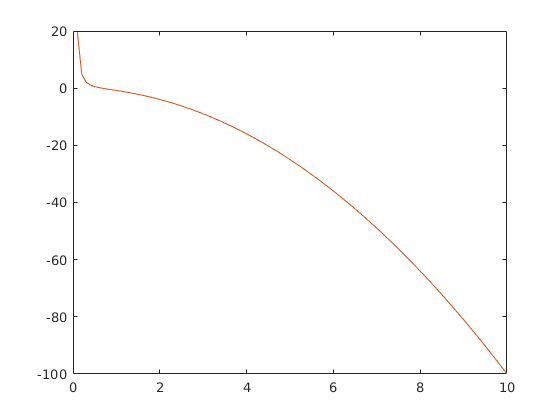

% -2, 2
y = 0 + 0.2.*x.^-2 -  1 .* x.^2;
m = 2;
p = [-2,2];
b = [0, 0.2,-1];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

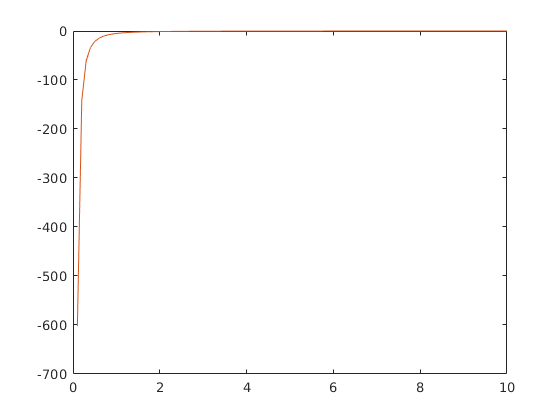

% -2, -2
y = 0 - 5.*x.^-2 +  0.5 .* x.^-2 .* log(x);
m = 2;
p = [-2,-2];
b = [0, -5,0.5];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

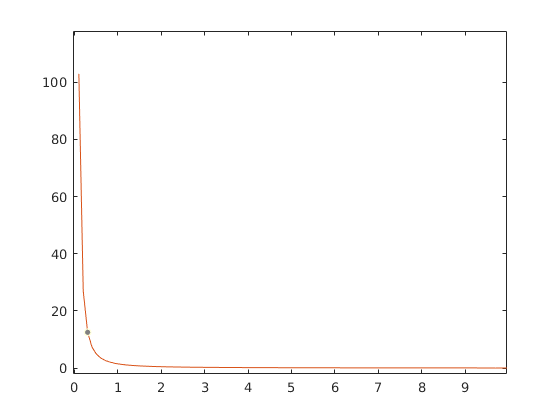

% -2 -1
y = 0 + 1.*x.^-2 +  0.5 .* x.^-1;
m = 2;
p = [-2,-1];
b = [0, 1,0.5];
yp = fracpoly(x, m, b, p);
plot(x,y, x,yp)

Now I sample random coefficents for p = (-2,2).

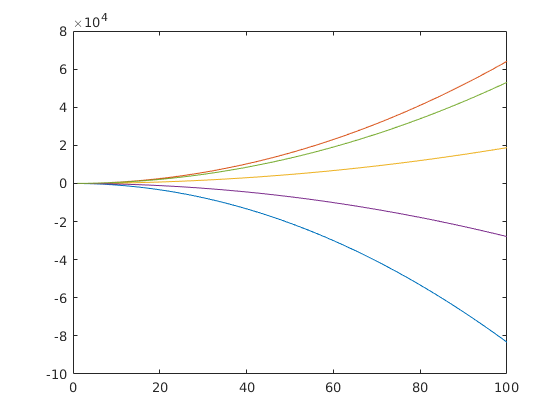

x = linspace(0, 100, 100);
bs = 5.*randn(5,3) + unifrnd(-1,1,5,3);
m = 2;
p = [-2,2];

y1 = fracpoly(x, m, bs(1, :), p);
y2 = fracpoly(x, m, bs(2, :), p);
y3 = fracpoly(x, m, bs(3, :), p);
y4 = fracpoly(x, m, bs(4, :), p);
y5 = fracpoly(x, m, bs(5, :), p);

plot(x,y1,x,y2,x,y3,x,y4,x,y5)

Try interactive features.

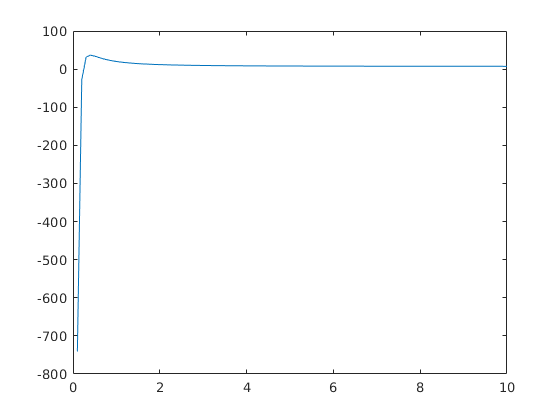

b0 = 7;
b1 = 13;
b2 = 9;
p1 = -2;
p2 = -2;
y = fracpoly(x, 2, [b0, b1, b2], [p1,p2]);
plot(x,y)